# Neuron output

In this exercise, a simulation of a neuron is demonstrated. The neuron is constructed by two inputs (x1, x2), weights (w1, w2), bias (b), transfer function (f), and results in output (Y). You can vary all neuron parameters (w1, w2, b, f) and inputs (x1, x2), and observe how they influence the neuron output.

The neuron can be constructed either manually (section Calculate neuron output) or as a simple neural network (section Construct neuron as a neural network). Finally, for both construction methods, the neuron output is calculated and shown for a range of inputs.

2022 © Primož Potočnik ([University of Ljubljana](https://www.uni-lj.si), [Faculty of Mechanical Engineering](https://www.fs.uni-lj.si))

## Neuron

The figure below shows the architecture of a simple neuron with two inputs (x1, x2), weights (w1, w2), bias (b), transfer function (f), and results in output (Y).

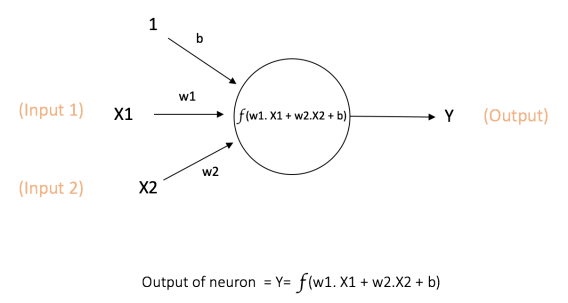


## Define neuron parameters

Choose various neuron parameters (w1, w2, b, f)

close all, clear, clc, format compact

% Neuron weights
w1 = 2;
w2 = -0.9;
w = [w1 w2];

% Neuron bias
b = -1.7;

% Transfer function (f)
%  tansig  - Hyperbolic tangent sigmoid transfer function
%  purelin - Linear transfer function
%  hardlim - Hard-limit transfer function
%  logsig  - Log-sigmoid transfer function
f = "tansig";

## Calculate neuron output

Play with various inputs (x1, x2) and observe the manually calculated neuron output.

x1 =0.5; % input 1
x2 =-1.7; % input 2
input = [x1 x2];

activation_potential = input*w'+b

activation_potential = 0.8300

neuron_output = feval(f, activation_potential)

neuron_output = 0.6805

Calculate neuron output based on neuron inputs

## Plot neuron output over the range of inputs

Create a meshgrid and plot neuron output over the area of inputs.

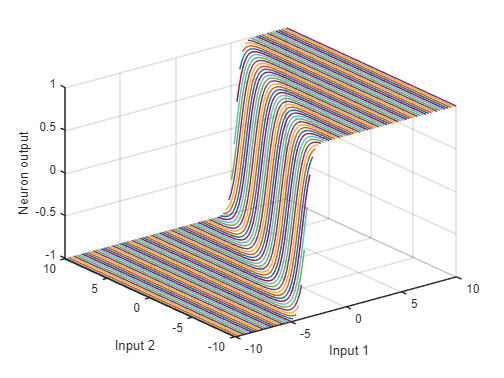

% plot neuron output over the range of inputs
[x1,x2] = meshgrid(-10:.25:10);
z = feval(f, [x1(:) x2(:)]*w'+b );
z = reshape(z,length(x1),length(x2));
plot3(x1,x2,z)
grid on
xlabel('Input 1')
ylabel('Input 2')
zlabel('Neuron output')

## Construct neuron as a neural network

Apply neural network toolbox functions to construct a neuron as a simple neural network and plot neuron output over the range of inputs.

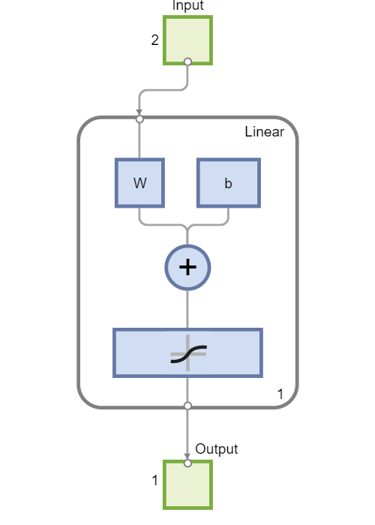

% create a simple neural network with one neuron (without hidden layers)
net = linearlayer;

% configure net
net = configure(net,input',1);

% set transfer function
net.layers{1}.transferFcn = f;

% set weights and bias
net.iw{1} = w;
net.b{1}  = b;

% show net
view(net)

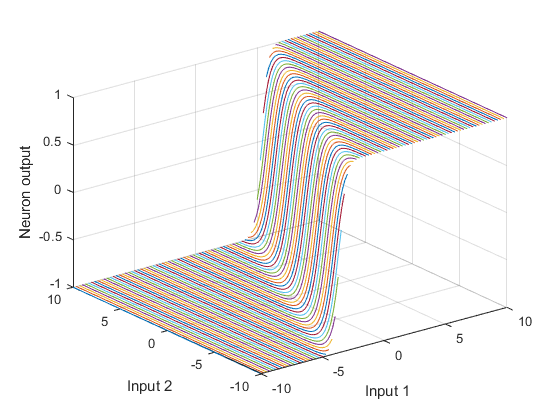

% plot neuron output over the range of inputs
net_output = net([x1(:) x2(:)]');
z = reshape(net_output,length(x1),length(x2));
figure
plot3(x1,x2,z)
grid on
xlabel('Input 1')
ylabel('Input 2')
zlabel('Neuron output')

Notice that the figure with a neuron response (encoded as a neural network) is the same as above (manually encoded).

% close all windows
close all force

## PowerPoint presentation

[NN2a_Neuron_and_architectures.pptx](matlab:open('./NN2a_Neuron_and_architectures.pptx'))